## * CALISTA MAIN SCRIPT *

Example 8.Identification of mouse spinal cord neurons activity during behavior (`Example_8_SATHYAMURTHY_DropNc_seq.m` script in the main folder of CALISTA)

Analysis of snRNA-seq data of Sathyamurthy et al. ([Sathyamurthy, A. et al. Massively Parallel Single Nucleus Transcriptional Profiling Defines Spinal Cord Neurons and Their Activity during Behavior. Cell Rep. 22, 2216–2225 (2018)](https://www.cell.com/cell-reports/fulltext/S2211-1247(18)30158-X)).

We begin with changing the current directory in MATLAB to the CALISTA folder. Type '`cd`' in the command window then copy and paste the current path in '`curr_path`':

clc
clear all
close all

% Add path for CALISTA folder:
% mfilename=matlab.desktop.editor.getActiveFilename;
% curr_path=fileparts(which(mfilename));

% In windows
% curr_path='C:\Users\npgao\polybox\AAA ETH project CALISTA\CALISTA-MATLAB 1.2 dropout\CALISTA-MATLAB 1.2.1';
% In MacOS
curr_path='/Users/nan/polybox/AAA ETH project CALISTA/CALISTA-MATLAB 1.2 dropout/CALISTA-MATLAB 1.2.1';

cd(curr_path);
addpath(genpath(curr_path))
warning ('off','all');

## * 1-Data Import and Preprocessing *

Type '`help import_data`' in the command window for more information 

Run the following section and import Sathyamurthy dataset (available in the subfolder *EXAMPLES/SATHYAMURTHY*).



**** Please upload normalized data. File formats accepted: .txt , .xlxs , .csv, .mat, .loom ****


Filtering genes by number of cells...

Filtering cells by number of genes...

% of zeros in the data  96.20

Scaling the data...

Selecting most variable genes...


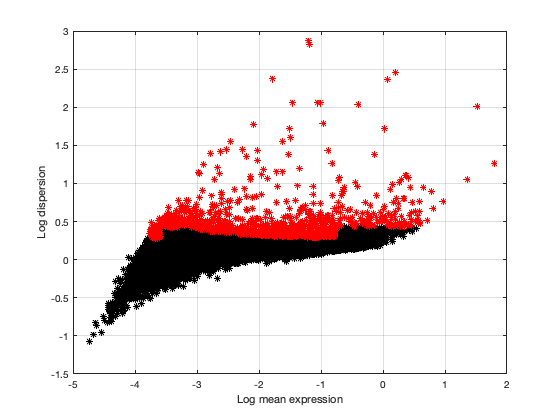


Normalizing the data...

Dropout estimation...


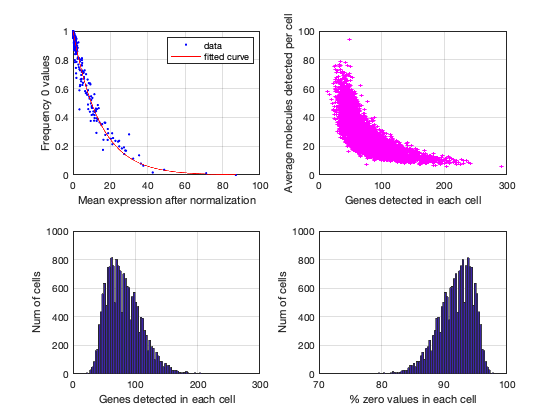


Top genes selection...


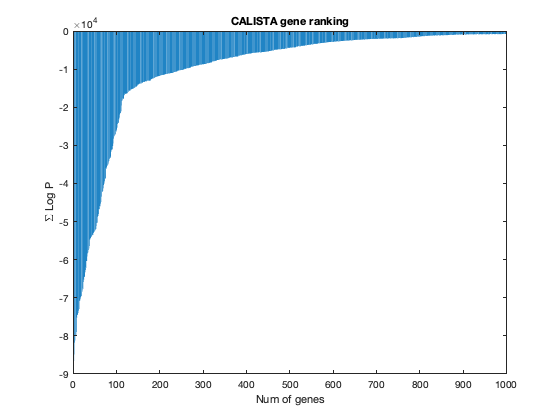


Finishing setup of the CALISTA data structure...

DONE.


%% *** 1-Data Import and Preprocessing ***
%
% Type 'help import_data' for more information 
%
% Specify pre-processing settings
INPUTS.data_type=5; % snRNA-seq data
INPUTS.format_data=6; % (RECOMMENDED FOR Droplet-based datasets) File .mat containing the following variables:
%                       'expMatrix': NxG expression matrix with rows=cells and columns=genes;
%                       'cellID': cell array/character vector containing cell IDs (not required)
%                       'geneNAMES': cell array containing gene names (not required)
%                       'timeline': 1xN numerical vector containing the time information (not required)
INPUTS.zeros_genes=3; % Remove genes with > 3 zero values
INPUTS.zeros_cells=200; % Remove cells with zero values>200
INPUTS.top_genes=300; % Retain only top 300 most variable genes
%
% Specify single-cell clustering settings
INPUTS.optimize=1; % The number of cluster is known a priori
INPUTS.max_clusters=20; % Max num of clusters
INPUTS.plot_tsne=1; % Plot tsne
INPUTS.tsne_opts.perplexity = 15; % tsne perplexity
INPUTS.tsne_opts.input_data = 5; % use top 5 PCs as input data
% 

% Upload and pre-process data 
[DATA,INPUTS] = import_data(INPUTS);

CALISTA processes the data from each time point separately.

## * 2-SINGLE-CELL CLUSTERING *

Type '`help CALISTA_clustering_main`' in the command window for more information. 

The number of clusters is determined using the eigengap plot. According to the eigengap plot below, we set the number of clusters to **9**.


Detecting the optimal number of clusters with Eigengap heuristics...
Starting parallel pool (parpool) using the 'local' profile ...
connected to 6 workers.



CALISTA_clustering is running...
Progress:
....................
||||||||||||||||||||

Constructing consensus matrix...
Elapsed time is 89.884052 seconds.


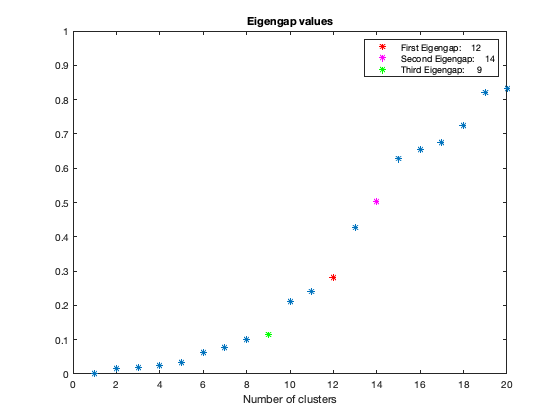


CALISTA_clustering is running...
Progress:
....................
||||||||||||||||||||

Best cell assignment...
Elapsed time is 79.442203 seconds.

No time info found. Please enter the starting cell or the marker gene whenever available

Skip relabelling step

Plotting...


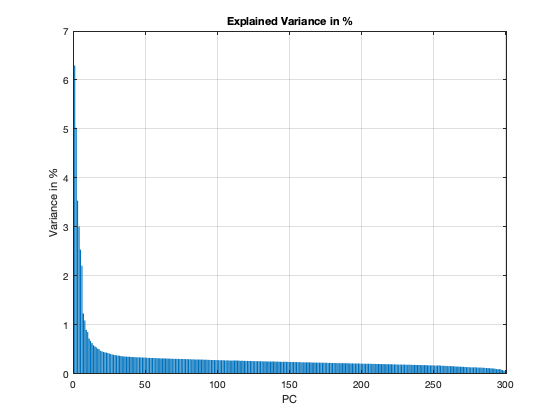

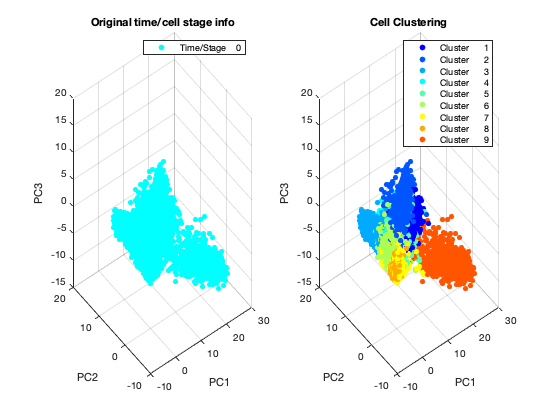

Elapsed time is 176.788057 seconds.

DONE.


[Results, DATA, INPUTS]=CALISTA_clustering_main(DATA,INPUTS);

We can load the list of marker genes and visualize the mean expression of each predicted cluster:

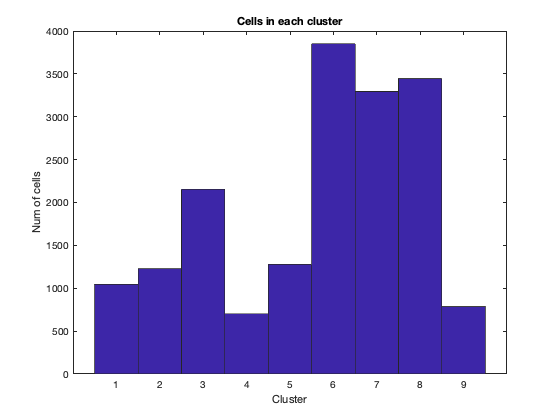

figure
hist(Results.final_groups,1:Results.expected_clusters)
title('Cells in each cluster')
xlabel('Cluster')
ylabel('Num of cells')

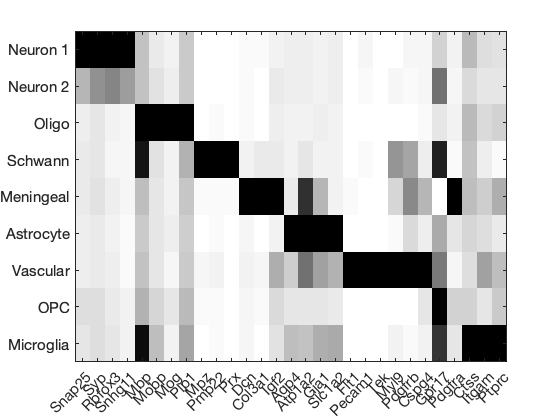

%% Upload marker genes

[FileName,PathName,FilterIndex] = uigetfile('*.*');
filename=strcat(PathName, FileName);
imported_data=importdata(filename);
[~,idx_marker_genes]=ismember(imported_data,DATA.original_genes);

testing_data=DATA.original_totDATA(:,idx_marker_genes);
mean_exp_marker_genes=[];
for i=1:Results.expected_clusters
    temp_data=testing_data(find(Results.final_groups==i),:);
    mean_exp_marker_genes(i,:)=mean(temp_data);%sum(temp_data, 1) ./ sum(temp_data~=0, 1);%mean(temp_data);%sum(temp_data, 1) ./ sum(temp_data~=0, 1);%
    
end
 mean_exp_marker_genes(isnan( mean_exp_marker_genes))=0;
 % Normalize each gene marker by the max value
 mean_exp_marker_genes=100*mean_exp_marker_genes./repmat(max(mean_exp_marker_genes),Results.expected_clusters,1);
%  cgo = clustergram(mean_exp_marker_genes,'Cluster',1,'Colormap',redbluecmap,'Standardize','column')
figure
imagesc(mean_exp_marker_genes([8 7 3 4 1 2 9 6 5],:))
colormap(flipud(gray))
set(gca, 'XTick', 1:1:length(imported_data), 'XTickLabel',imported_data,'FontSize',15);
xtickangle(45)
clusterID={'Neuron 1','Neuron 2','Oligo','Schwann','Meningeal','Astrocyte','Vascular','OPC','Microglia'};
set(gca, 'YTick', 1:1:Results.expected_clusters, 'YTickLabel',clusterID);

% ytickangle(45)